# Expand Example 3.47:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

The 10-ms pulse signal $x(t)=\Pi(100t)$ is applied to a first-order RC circuit with 3-dB cutoff frequency of $f_{c}$.  The system function for the RC circuit is

        
$$H(f)=\frac{1}{1+j(f/f_{c})$$


The Fourier transform of the input signal is

        
$$X(f)=0.01\,\textrm{sinc}(0.01 f)$$


fc = 80;  % 3-dB cutoff frequency
% Define an anonymous function for H(f)
H = @(f) 1./(1+j*f/fc);
% Anonymous function for X(f)
X = @(f) 0.01*sinc(0.01*f);
% Compute the Fourier transform of the output signal
Y = @(f) H(f).*X(f);

Graph the system function as well as the output spectrum.

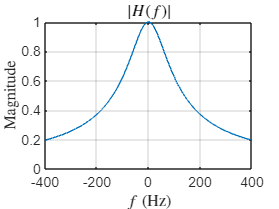

f = [-400:0.1:400];
plot(f,abs(H(f))); grid;
set(0,'defaultTextInterpreter','latex');
xlabel('$f$ (Hz)');
ylabel('Magnitude');
title('$|H(f)|$');

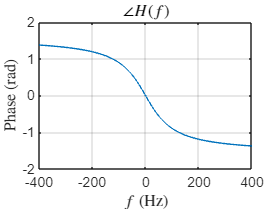

plot(f,angle(H(f))); grid;
xlabel('$f$ (Hz)');
ylabel('Phase (rad)');
title('$\angle H(f)$');

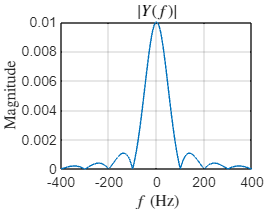

plot(f,abs(Y(f))); grid;
xlabel('$f$ (Hz)');
ylabel('Magnitude');
title('$|Y(f)|$');

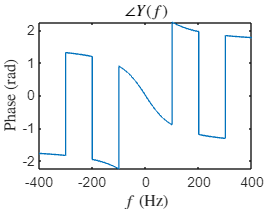

plot(f,angle(Y(f)));
xlabel('$f$ (Hz)');
ylabel('Phase (rad)');
title('$\angle Y(f)$');

set(0,'defaultTextInterpreter','tex');